# Step 3 - Imparting a 16 pixel radius blur

## Gaussian Blur

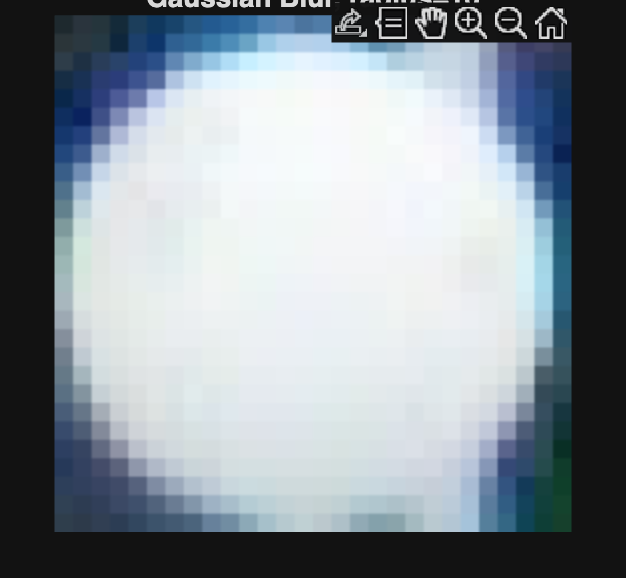

% Standard deviation roughly related to radius
I = imread('1.png');
sigma = 16;  
I_gauss = imgaussfilt(I_up, sigma);

figure; imshow(I_gauss); title('Gaussian Blur, radius=16');

## Triangle Blur

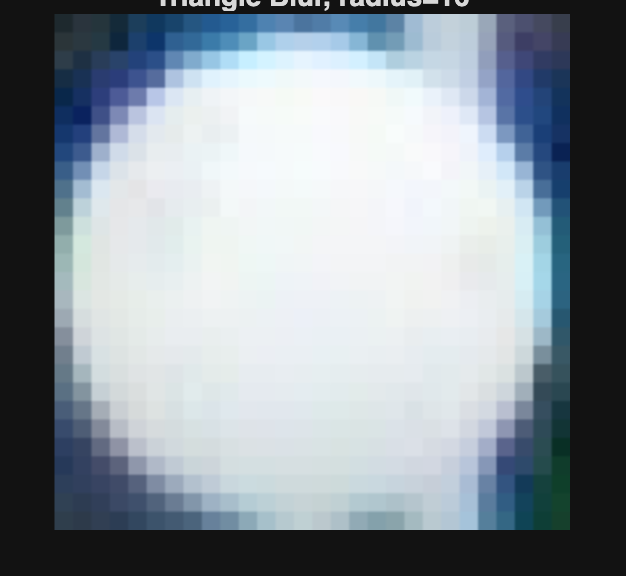

r = 16;

% First blur with box filter
h_box = fspecial('average', 2*r+1);
I_tmp = imfilter(I_up, h_box, 'replicate');

% Blur again with the same box filter
I_tri = imfilter(I_tmp, h_box, 'replicate');

imshow(I_tri); title('Triangle Blur, radius=16');

## Top-hat/box Blur

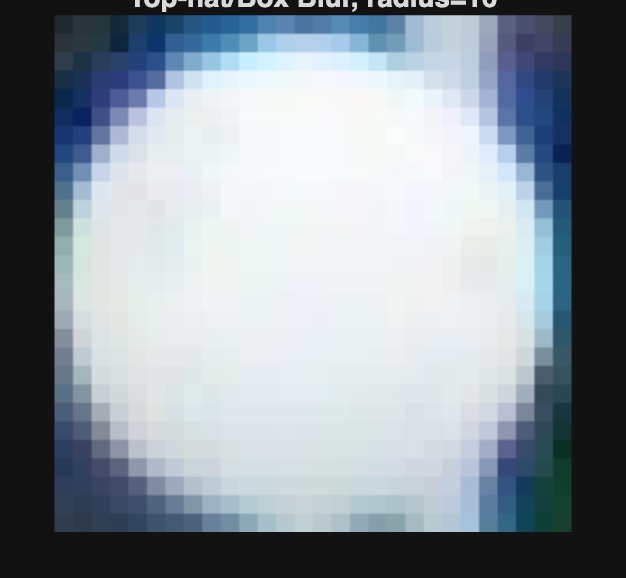

r = 16;
h = fspecial('average', 2*r+1);   % square box kernel, side=2r+1
I_box = imfilter(I_up, h, 'replicate');

figure; imshow(I_box); title('Top-hat/Box Blur, radius=16');

## Sinc Blur

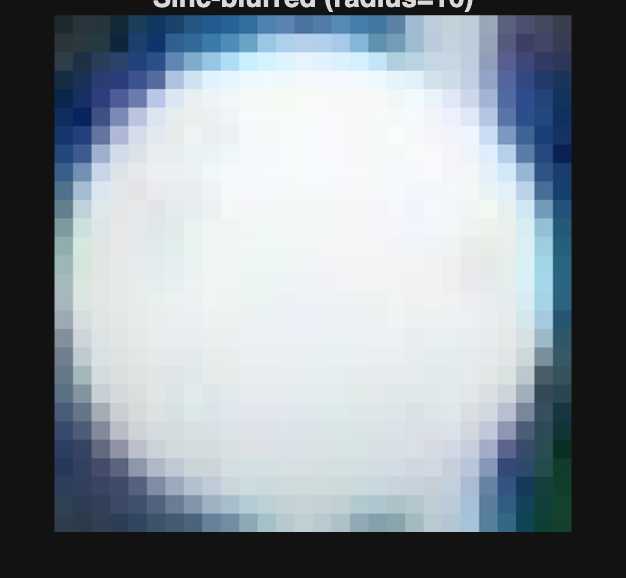

I_up_d = im2double(I_up);          % work in double

% Sinc blur parameters
r = 16;                % effective radius in pixels
sz = 4*r + 1;          % kernel size (odd)

% Create coordinate grid (centered)
[x, y] = meshgrid(-2*r:2*r, -2*r:2*r);
R = sqrt(x.^2 + y.^2);         % radial distance

% Build 2D sinc kernel explicitly: sin(pi * R/r) / (pi * R/r)
arg = pi * (R / r);
sinc_kernel = ones(size(R));   % initialize (R==0 --> 1)
nz = (R ~= 0);
sinc_kernel(nz) = sin(arg(nz)) ./ arg(nz);  % safe division

% Build 2D Hann window without using 'hann' function (works anywhere)
n = (0:sz-1)'; 
hann1 = 0.5 * (1 - cos(2*pi*n/(sz-1)));    % 1D Hann
window2d = hann1 * hann1';                 % outer product -> 2D

% Window the sinc and normalize
h_sinc = sinc_kernel .* window2d;
h_sinc = h_sinc / sum(h_sinc(:));

% Apply the filter (imfilter will apply to each color channel)
I_sinc = imfilter(I_up_d, h_sinc, 'replicate');

% Display
figure;

imshow(I_sinc);   title('Sinc-blurred (radius=16)');